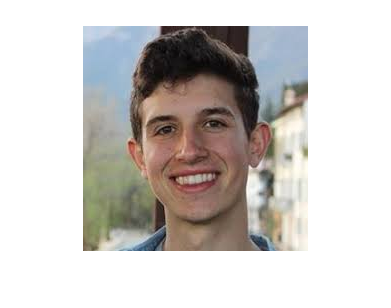

im= imread("ranper.jpg");
imshow(im);

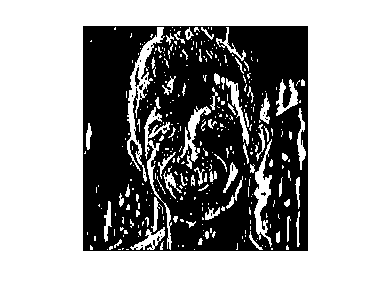


% overexposed(im);
edge_detect(im, 20, "ver");

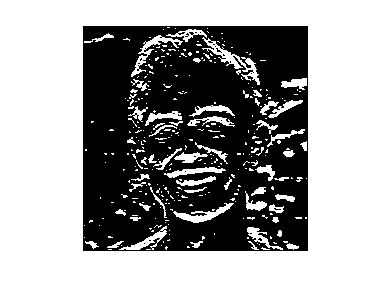

edge_detect(im, 20, "hor");

% RGB(im);
% object_detect(im, 20 ,"ver");
% siz = size(im)
% % lengt = length(im)
% 
% rows = siz(1)
% cols = siz(2)
% 
% R = im(:,:,1); 
% G = im(:,:,2); 
% B = im(:,:,3);
% R(25, 25)
% G(25, 25)
% B(25, 25)
% new = uint8(zeros(rows, cols, 3));
% 
% % a = im(convert(9, 0))
% mat = zeros(10, 10);
% % b = im(10, 1)
% for i = 1:10
%     for j = 1:10
%         mat(i, j) = 1/10;
%     end
% end
% % mat = [0.25 0 -0.25;
% %        0.5 0 -0.5;
% %        0.25 0 -0.25]
% % uint8(mat)
% % newmat = [im(i-1, j-1) im(i-1, j) im(i-1, j+1) im(i, j-1) im(i, j) im(i, j+1) im(i+1, j-1) im(i+1, j) im(i+1, j+1)]
% % c = newmat+mat
% 
% for i = 2:rows-1
%     for j = 2:cols-1
%         newmatR = [R(i-1, j-1) R(i-1, j) R(i-1, j+1); R(i, j-1) R(i, j) R(i, j+1); R(i+1, j-1) R(i+1, j) R(i+1, j+1)];
%         newmatG = [G(i-1, j-1) G(i-1, j) G(i-1, j+1); G(i, j-1) G(i, j) G(i, j+1); G(i+1, j-1) G(i+1, j) G(i+1, j+1)];
%         newmatB = [B(i-1, j-1) B(i-1, j) B(i-1, j+1); B(i, j-1) B(i, j) B(i, j+1); B(i+1, j-1) B(i+1, j) B(i+1, j+1)];
% 
% %         conR = conv2(mat, newmatR);
% %         conG = conv2(mat, newmatG);
% %         conB = conv2(mat, newmatB);
% % 
% %         sR = sum(conR, 'all');
% %         sG = sum(conG, 'all');
% %         sB = sum(conB, 'all');
% % %         con = conv2(newmat, mat);
%         conR = double(newmatR).*mat;
%         conG = double(newmatG).*mat;
%         conB = double(newmatB).*mat;
%         sR = sum(conR, 'all');
%         sG = sum(conG, 'all');
%         sB = sum(conB, 'all');
% %         s = sum(con);
%         if sR+sG+sB>7
%             new(i, j, 1) = 255;
%             new(i, j, 2) = 255;
%             new(i, j, 3) = 255;
% %         end
%         else 
%             new(i, j, 1) = 0;
%             new(i, j, 2) = 0;
%             new(i, j, 3) = 0;
%         
%         end
% %         new(i, j, 1) = R(i, j);
% %         new(i, j, 2) = G(i, j);
% %         new(i, j, 3) = B(i, j);
%         
% %         map(convert(i, j),:);
%     end
% end
% 
% % c = new(10, 1)
% imshow(new);
% % im
% new
% colormap(mape);



function val = convert(rows, cols)
    val = cols + rows*183;
end

function overexposed(im)

    siz = size(im);
    rows = siz(1);
    cols = siz(2);

    R = im(:,:,1); 
    G = im(:,:,2); 
    B = im(:,:,3);
    new = uint8(zeros(rows, cols, 3));
    

    mat = [1/9 1/9 1/9; 1/9 1/9 1/9; 1/9 1/9 1/9];

    for i = 2:rows-1
        for j = 2:cols-1
            newmatR = [R(i-1, j-1) R(i-1, j) R(i-1, j+1); R(i, j-1) R(i, j) R(i, j+1); R(i+1, j-1) R(i+1, j) R(i+1, j+1)];
            newmatG = [G(i-1, j-1) G(i-1, j) G(i-1, j+1); G(i, j-1) G(i, j) G(i, j+1); G(i+1, j-1) G(i+1, j) G(i+1, j+1)];
            newmatB = [B(i-1, j-1) B(i-1, j) B(i-1, j+1); B(i, j-1) B(i, j) B(i, j+1); B(i+1, j-1) B(i+1, j) B(i+1, j+1)];
    
            conR = conv2(mat, newmatR);
            conG = conv2(mat, newmatG);
            conB = conv2(mat, newmatB);
    
            sR = sum(conR, 'all');
            sG = sum(conG, 'all');
            sB = sum(conB, 'all');
    
            new(i, j, 1) = sR;
            new(i, j, 2) = sG;
            new(i, j, 3) = sB;
        end
    end

    imshow(new);
end


function edge_detect(im, weight, orientation)

    siz = size(im);
    rows = siz(1);
    cols = siz(2);
    
    R = im(:,:,1); 
    G = im(:,:,2); 
    B = im(:,:,3);
    new = uint8(zeros(rows, cols, 3));

    if orientation == "ver"
        mat = [0.25 0 -0.25;
               0.5 0 -0.5;
               0.25 0 -0.25];
    elseif orientation == "hor"
        mat = [0.25 0.5 0.25;
               0 0 0;
               -0.25 -0.5 -0.25];
    end
    
    for i = 2:rows-1
        for j = 2:cols-1
            newmatR = [R(i-1, j-1) R(i-1, j) R(i-1, j+1); R(i, j-1) R(i, j) R(i, j+1); R(i+1, j-1) R(i+1, j) R(i+1, j+1)];
            newmatG = [G(i-1, j-1) G(i-1, j) G(i-1, j+1); G(i, j-1) G(i, j) G(i, j+1); G(i+1, j-1) G(i+1, j) G(i+1, j+1)];
            newmatB = [B(i-1, j-1) B(i-1, j) B(i-1, j+1); B(i, j-1) B(i, j) B(i, j+1); B(i+1, j-1) B(i+1, j) B(i+1, j+1)];

            conR = double(newmatR).*mat;
            conG = double(newmatG).*mat;
            conB = double(newmatB).*mat;
            sR = sum(conR, 'all');
            sG = sum(conG, 'all');
            sB = sum(conB, 'all');

            if sR+sG+sB>weight
                new(i, j, 1) = 255;
                new(i, j, 2) = 255;
                new(i, j, 3) = 255;
            else 
                new(i, j, 1) = 0;
                new(i, j, 2) = 0;
                new(i, j, 3) = 0;  
            end
        end
    end
    imshow(new);
end

function RGB(im)
    siz = size(im);
    rows = siz(1);
    cols = siz(2);
    
    R = im(:,:,1); 
    G = im(:,:,2); 
    B = im(:,:,3);
    newR = uint8(zeros(rows, cols, 3));
    newG = uint8(zeros(rows, cols, 3));
    newB = uint8(zeros(rows, cols, 3));

    for i = 2:rows
        for j = 2:cols
            newR(i, j, 1) = R(i,j);
            newR(i, j, 2) = 0;
            newR(i, j, 3) = 0;

            newG(i, j, 1) = 0;
            newG(i, j, 2) = G(i, j);
            newG(i, j, 3) = 0;

            newB(i, j, 1) = 0;
            newB(i, j, 2) = 0;
            newB(i, j, 3) = B(i, j);

        end
    end
figure;
imshow(newR);
figure;
imshow(newG);
figure;
imshow(newB);

end

function object_detect(im, weight, orientation)
    siz = size(im);
    rows = siz(1);
    cols = siz(2);
    a = 0;
    
    R = im(:,:,1); 
    G = im(:,:,2); 
    B = im(:,:,3);
    new = uint8(zeros(rows, cols, 3));

    if orientation == "ver"
        mat = [0.25 0 -0.25;
               0.5 0 -0.5;
               0.25 0 -0.25];
    elseif orientation == "hor"
        mat = [0.25 0.5 0.25;
               0 0 0;
               -0.25 -0.5 -0.25];
    end
    
    for i = 2:rows-1
        for j = 2:cols-1
            newmatR = [R(i-1, j-1) R(i-1, j) R(i-1, j+1); R(i, j-1) R(i, j) R(i, j+1); R(i+1, j-1) R(i+1, j) R(i+1, j+1)];
            newmatG = [G(i-1, j-1) G(i-1, j) G(i-1, j+1); G(i, j-1) G(i, j) G(i, j+1); G(i+1, j-1) G(i+1, j) G(i+1, j+1)];
            newmatB = [B(i-1, j-1) B(i-1, j) B(i-1, j+1); B(i, j-1) B(i, j) B(i, j+1); B(i+1, j-1) B(i+1, j) B(i+1, j+1)];

            conR = double(newmatR).*mat;
            conG = double(newmatG).*mat;
            conB = double(newmatB).*mat;
            sR = sum(conR, 'all');
            sG = sum(conG, 'all');
            sB = sum(conB, 'all');

            if sR+sG+sB>weight
                if a == 0
                    a = 1;
                else
                    a = 0;
                end 
            else
                a = 1;
            end

            if a == 1
                new(i, j, 1) = 255;
                new(i, j, 2) = 255;
                new(i, j, 3) = 255;
            else
                new(i, j, 1) = 0;
                new(i, j, 2) = 0;
                new(i, j, 3) = 0;  
            end
        end
    end
    imshow(new);
end